# Test Diffuse Correlation Spectroscopy (DCS)

close all
clear variables
clc

## display properties

set(0, 'DefaultAxesFontname', 'Arial CE');
font_size = 16;
set(0, 'DefaultAxesFontsize', font_size);
set(0, 'defaulttextfontname', 'Arial CE');
set(0, 'defaulttextfontsize', font_size);
set(0, 'defaultfigurecolor', 'w');

## BODY

## set the 'nirfasterroot' as current folder

cd(nirfasterroot);

## test DCS on standard mesh:

% forward data 3D
mesh = load_mesh('cylinder_dcs');

Sources integration functions loaded
Recalculating integration functions as there is some mismatch
Detectors integration functions loaded
Recalculating integration functions as there is some mismatch



%autocorrelation time
tau_DCS = logspace(-7,-3,128);

%autocorrelation data
data_DCS = femdata_DCS(mesh,tau_DCS);

## electric field temporal autocorrelation

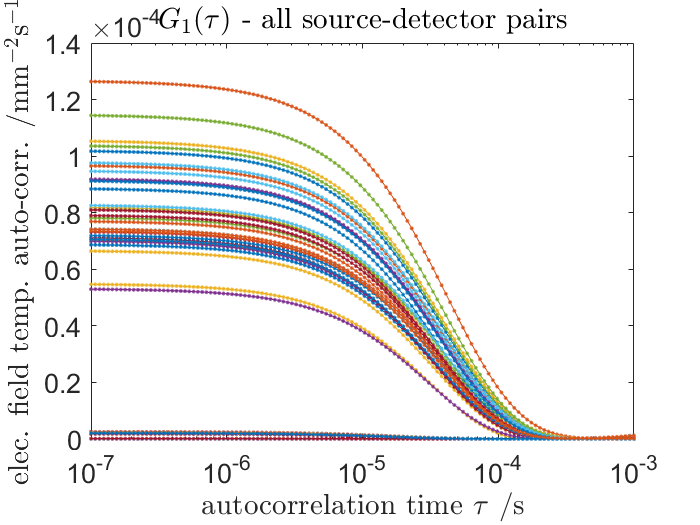

figure('Name',mesh.name)
semilogx(tau_DCS,data_DCS.G1_DCS','.-')
title('$G_{1}(\tau)$ - all source-detector pairs','Interpreter','latex');
xlabel('autocorrelation time $\tau$ /s','Interpreter','latex')
ylabel('elec. field temp. auto-corr. /mm$^{-2}$s$^{-1}$','Interpreter','latex')

## normalized electric field temporal autocorrelation function

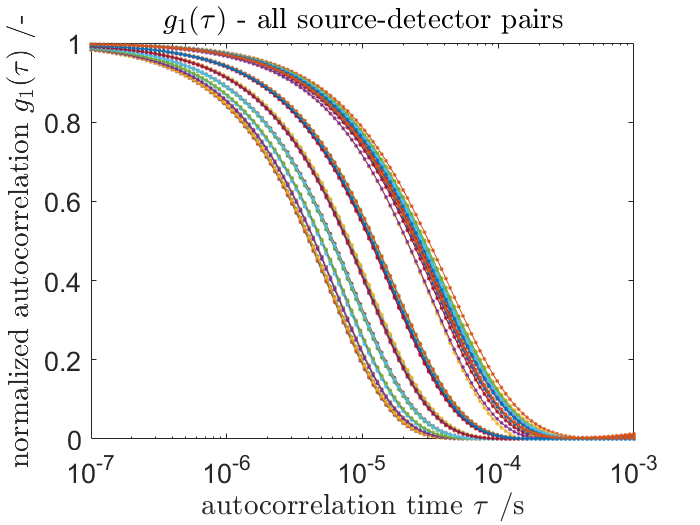

figure('Name',mesh.name)
semilogx(tau_DCS,data_DCS.G1_DCS./data_DCS.amplitude,'.-')
title('$g_{1}(\tau)$ - all source-detector pairs','Interpreter','latex');
xlabel('autocorrelation time $\tau$ /s','Interpreter','latex')
ylabel('normalized autocorrelation $g_{1}(\tau)$ /-','Interpreter','latex')